## Задание 1. Одноканальная система в форме вход-выход 

Объявим переменные для этого задания

a2 = 6;
a1 = 11;
a0 = 6;
b2 = 6;
b1 = 4;
b0 = 16;

Параметры для запуска симуляции

simTimeStart = 0;
simTimeEnd = 10;
step = 0.02;
data.time=(simTimeStart:0.02:simTimeEnd)';
input=ones(1, length(data.time))';
data.signals(1).values=input;
data.signals(1).dimensions=1;
data.signals(2).values=input;
data.signals(2).dimensions=1;

Визуализируем 

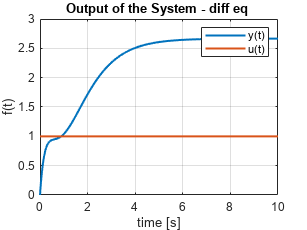

modelName = 'task1'; 
load_system(modelName);                       
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.tout;                
y_out = out.yout{1}.Values.data;  

figure;
plot(time, y_out, 'LineWidth', 1.5); 
hold on;
plot(time, input, 'LineWidth', 1.5); 
title('Output of the System - diff eq ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t)','u(t)');
save_file('output_task1_diff_eq')

Проверяем через передаточную функцию:

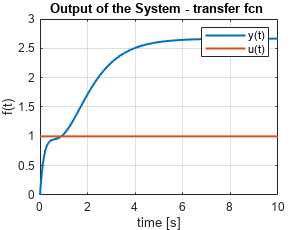

y_out = out.yout{2}.Values.data;  

figure;
plot(time, y_out, 'LineWidth', 1.5); 
hold on;
plot(time, input, 'LineWidth', 1.5); 
title('Output of the System - transfer fcn ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t)','u(t)');
save_file('output_task1_transfer_fcn')

## Задание 2. Переход от формы вход-выход к форме вход-состояние-выход 

Объявим переменные, матрицы для этого задания:

a2 = 6;
a1 = 11;
a0 = 6;
b2 = 6;
b1 = 4;
b0 = 16;

**Каноническая управляемая форма:**

A1 = [0 1 0; 
      0 0 1; 
      -a0 -a1 -a2];
B1 = [0;
      0;
      1;];
C1 = [b0; b1; b2];

**Каноническая наблюдаемая форма:**

A2 = [0 0 -a0; 
      1 0 -a1; 
      0 1 -a2];
B2 = [b0;
      b1;
      b2;];
C2 = [0; 0; 1];

**Диагональная форма:**

lambda1 = -2; lambda2 = -3; lambda3 = -1;
beta1 = -8; beta2 = 29; beta3 = 3;
gamma1 = 4; gamma2 = 1; gamma3 = 3;

A3 = [lambda1   0     0; 
        0     lambda2 0; 
        0       0  lambda3];
B3 = [beta1;
      beta2;
      beta3;];
C3 = [gamma1; gamma2; gamma3];

Параметры для запуска симуляции

simTimeStart = 0;
simTimeEnd = 10;
step = 0.02;
data.time=(simTimeStart:0.02:simTimeEnd)';
input=ones(1, length(data.time))';
data.signals(1).values=input;
data.signals(1).dimensions=1;
data.signals(2).values=input;
data.signals(2).dimensions=1;
data.signals(3).values=input;
data.signals(3).dimensions=1;

Запускаем - 1

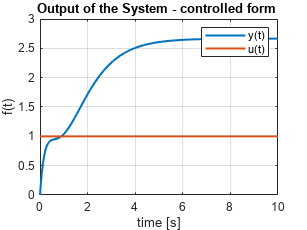

modelName = 'task2'; 
load_system(modelName);                       
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.tout;                
y_out = squeeze(out.yout{1}.Values.data);  

figure;
plot(time, y_out, 'LineWidth', 1.5); 
hold on;
plot(time, input, 'LineWidth', 1.5); 
title('Output of the System - controlled form ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t)','u(t)');
save_file('output_task2_controlled')

Запускаем - 2

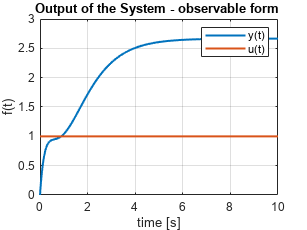

y_out = squeeze(out.yout{2}.Values.data);  

figure;
plot(time, y_out, 'LineWidth', 1.5); 
hold on;
plot(time, input, 'LineWidth', 1.5); 
title('Output of the System - observable form ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t)','u(t)');
save_file('output_task2_observable')

Запускаем - 3

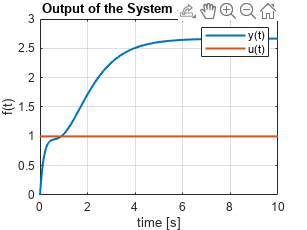

y_out = squeeze(out.yout{3}.Values.data);  

figure;
plot(time, y_out, 'LineWidth', 1.5); 
hold on;
plot(time, input, 'LineWidth', 1.5); 
title('Output of the System - diagonal form ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t)','u(t)');
save_file('output_task2_diagonal')

## Задание 3. Многоканальная система в форме вход-выход

% Определение символьной переменной p
syms p;

A = [p+14 p+2; 
     p+7 p+3;];
B = [2 8; 
    9 4;];

W1 = A^-1 * B

$$W1 = \begin{array}{l} \left(\begin{array}{cc} \frac{p+3}{\sigma_{2}}-\frac{9\,\left(p+2\right)}{\sigma_{1}} & \frac{2\,\left(p+3\right)}{2\,p+7}-\frac{p+2}{2\,p+7}\\ \frac{9\,\left(p+14\right)}{\sigma_{1}}-\frac{p+7}{\sigma_{2}} & \frac{p+14}{2\,p+7}-\frac{2\,\left(p+7\right)}{2\,p+7} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=4\,\left(2\,p+7\right)\\ \sigma_{2}=2\,\left(2\,p+7\right) \end{array}$$

W2 = simplify(W1) % simplified

$$W2 = \left(\begin{array}{cc} -\frac{7\,p+12}{4\,\left(2\,p+7\right)} & \frac{p+4}{2\,p+7}\\ \frac{7\,\left(p+16\right)}{4\,\left(2\,p+7\right)} & -\frac{p}{2\,p+7} \end{array}\right)$$

Параметры для запуска симуляции

simTimeStart = 0;
simTimeEnd = 10;
step = 0.02;
data.time=(simTimeStart:0.02:simTimeEnd)';
input1=ones(1, length(data.time))';
input2= 2*sin(data.time);
data.signals(1).values=input1;
data.signals(1).dimensions=1;
data.signals(2).values=input2;
data.signals(2).dimensions=1;

Запускаем - 1

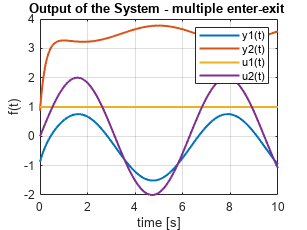

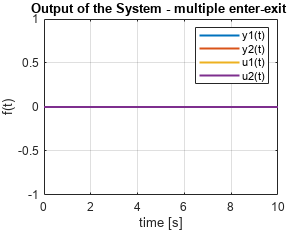

modelName = 'task3'; 
load_system(modelName);                       
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.tout;                
y_out1 = squeeze(out.yout{1}.Values.data);  
y_out2 = squeeze(out.yout{2}.Values.data);  
figure;
plot(time, y_out1, 'LineWidth', 1.5); 
hold on;
plot(time, y_out2, 'LineWidth', 1.5); 
hold on;
plot(time, input1, 'LineWidth', 1.5); 
hold on;
plot(time, input2, 'LineWidth', 1.5); 
title('Output of the System - multiple enter-exit ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y1(t)','y2(t)','u1(t)','u2(t)');
save_file('output_task3_multiple_EE_1')

## Задание 4. Многоканальная система в форме вход-состояние-выход

A = [0 -2;
     1 -3];
B = [2 3;
     3 5];
C = [3 5;
     4 7];


Параметры для запуска симуляции

simTimeStart = 0;
simTimeEnd = 10;
step = 0.02;
data.time=(simTimeStart:0.02:simTimeEnd)';
input1=ones(1, length(data.time))';
input2= 2*sin(data.time);
data.signals(1).values=input1;
data.signals(1).dimensions=1;
data.signals(2).values=input2;
data.signals(2).dimensions=1;

Запускаем - 1

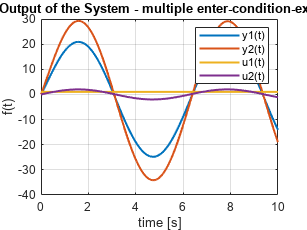

modelName = 'task4'; 
load_system(modelName);                       
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.tout;                
y_out1 = squeeze(out.yout{1}.Values.data);  
y_out2 = squeeze(out.yout{2}.Values.data);  
figure;
plot(time, y_out1, 'LineWidth', 1.5); 
hold on;
plot(time, y_out2, 'LineWidth', 1.5); 
hold on;
plot(time, input1, 'LineWidth', 1.5); 
hold on;
plot(time, input2, 'LineWidth', 1.5); 
title('Output of the System - multiple enter-condition-exit ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y1(t)','y2(t)','u1(t)','u2(t)');
save_file('output_task3_multiple_ECE')

**Функция, чтобы сохранить файл в папку**

function save_file(name)
    path = 'D:\Math\LinearSystemsOfAutoControl\linear_systems_labs\lab1\latex1\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end